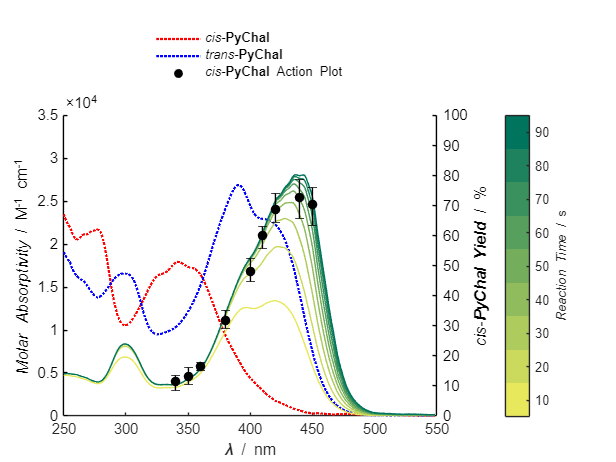

clear
phiIso1 = 0.1; %QY trans -> cis
phiIso2 = 0.5;  %QY cis -> trans
IIso = 6.43e15; %isomerisation photon flux
NA = 6.022e23; %Avagadro's Number
SmoothFactor = 10; %Smooth data stepsize (increments of spectrometer resolution)
concentrationUVVis = 20e-6; %Molar concentration of molecules in UV-Vis
concentrationExperiment = 10e-6; %Molar concentration of molecules used in experiment
volume = 2e-3; %Volume of sample
iTimecis = 10; %initial time
fTimecis = 90; %final time
timeStepcis = 9; %timestep (number of model graphs)

%import data
MonoAbsFile = 'PyChalTransMonomerACN.csv';
CisAbsFile = 'PyChalCisMonomerACN.csv';
CisAPFile = 'APCis.csv';
MonoAbs = readmatrix(MonoAbsFile);
CisAbs = readmatrix(CisAbsFile);
CisAP = readmatrix(CisAPFile); %AP = Action Plot

%smoothing and convert from Absorbance to Molar Absorptivity based on concentration
MolarAbsT = movmean(MonoAbs(1:342,2),SmoothFactor)/concentrationUVVis;
MolarAbsC = movmean(CisAbs(1:5:1710,2),SmoothFactor); %Abs data calculated from other spectrometer, so needs to be scaled

IsoLambda = linspace(250, 600, length(MolarAbsT));  %Wavelength Data

Isot = linspace(iTimecis, fTimecis, timeStepcis); %time vector
Isocmap = flip(summer(length(Isot))/1.1); %colourmap
IsoN0 = concentrationExperiment*NA*volume; %initial molecules #
Isoktc = phiIso1 * ((MolarAbsT*log(10)*10^3)/ NA) * IIso; %rate coefficient for ktrans->cis
Isokct = phiIso2 * ((MolarAbsC*log(10)*10^3)/ NA) * IIso; %rate coefficient for kcis->trans

%loop though each time for model
for j = 1:length(Isot)
    for i = 1:length(MolarAbsT)
        IsoNdLam(i) = rates2plus2(IsoN0, Isoktc(i), Isokct(i), Isot(j));
    end
    IsotimeNdLam{j} = IsoNdLam; % add each to cell
end

%plot all data
    figure
    hold on
    yyaxis left
    plot(IsoLambda,MolarAbsC, linestyle=":", linewidth=1.5, color='r')
    plot(IsoLambda,MolarAbsT, linestyle=":", linewidth=1.5, color='b')
    ylabel("{\itMolar Absorptivity} / M^{-1} cm^{-1}")
    ylim([0 35000])
    yyaxis right
for k = 1:length(IsotimeNdLam)    
    plot(IsoLambda,(IsotimeNdLam{k}/IsoN0)*100, 'Marker', 'none', linestyle="-", linewidth=1, color=Isocmap(k,:))
end
    scatter(CisAP(:,1), CisAP(:,2), "filled", MarkerFaceColor='k')
    errorbar(CisAP(:,1), CisAP(:,2), CisAP(:,3), CisAP(:,4), 'o', 'color', 'k');
    ax = gca;
    ax.YAxis(1).Color = 'k';
    ax.YAxis(2).Color = 'k';
    hold off
    xlabel("{\it\bf\lambda} / nm")
    ylabel("{\it{\itcis}-{\bfPyChal} Yield} / %")
    xlim([250 550])
    ylim([0 100])


    legend("{\itcis}-{\bfPyChal}", "{\ittrans}-{\bfPyChal}", "", "", "", "", "", "", "", "", "", "{\itcis}-{\bfPyChal} Action Plot", "Location","northoutside", 'box', 'off')

    colormap(Isocmap);
    cb = colorbar;
    cb.Ticks = linspace(0+(1/length(Isot)/2), 1-(1/length(Isot)/2), length(Isot));
    set(cb, 'TickLabels', linspace(Isot(1), Isot(end), length(Isot)));
    cb.Label.String = '{\itReaction Time} / s';

%rate model for photoisomerisation (Equation S4)
    function Nd = rates2plus2(N0, ktc, kct, t)
    k = ktc + kct;
    Kall = ktc/k;
    Nd = Kall*(N0)*(1-exp(-k.*t));
end

